str = "kulakov";
dis = sprintf("Изначальное сообщение: %s\n", str);
disp(dis);

Изначальное сообщение: kulakov



bit = 7;
x = char(str);
massage = encode(x);
dis = sprintf("Битовая последовательность: \n");
disp(dis);

Битовая последовательность: 



disp(num2str(massage));

1  1  0  1  0  1  1  1  0  1  0  1  1  1  0  0  1  1  0  1  1  1  0  0  0  0  1  1  1  1  0  1  0  1  1  1  1  1  1  0  1  1  0  1  1  0  1  1  1


dis = sprintf("\nБитовая последовательность после шифрования: \n");
disp(dis);


Битовая последовательность после шифрования: 



conv_massage = conv_encode(massage);

disp(num2str(conv_massage));

1  1  0  1  0  1  1  1  0  1  0  1  0  0  0  1  1  1  0  0  0  0  1  0  0  0  0  1  1  1  1  1  0  1  1  1  1  1  0  0  1  0  1  1  0  0  1  1  1  0  1  0  0  1  1  0  1  0  0  1  1  0  1  0  1  1  1  0  0  0  0  1  0  0  1  0  0  0  0  0  0  1  0  0  1  1  0  1  0  1  0  0  0  1  0  1  1  1



ran_index = randperm(length(conv_massage));
dis = sprintf("\nВектор перемежения: \n");
disp(dis);


Вектор перемежения: 



disp(num2str(ran_index));

88  49  36  16  58  98  56  80  59  74  61  20  91  26  75  24  65  90  51  76  46  35  93   9   4  47  21  86  33  22  95  14  92  77  13  81  83  87  72  71   5  55  39   2  10  94  50  28  38  54  67   8  60  82   7  45   3  41  42  11  85  69  27  84  66  12  23  57  34  53  30  25  64   1  37  29  19  70  79  44  63  62  73  78  43  17  48  32  31  40  18  97  96   6  68  52  89  15



interleave_massage = interleave(conv_massage, ran_index);
dis = sprintf("\nБитовая последовательность после перемежения: \n");
disp(dis);


Битовая последовательность после перемежения: 



disp(num2str(interleave_massage));

1  1  1  1  0  1  0  0  0  0  1  0  0  0  1  0  1  1  1  0  0  1  0  0  1  1  0  1  0  0  0  0  0  0  0  0  0  0  1  0  0  1  0  1  1  1  0  1  1  1  1  1  1  1  1  0  0  1  0  0  1  0  0  0  1  1  1  1  1  0  1  0  0  1  1  1  0  0  0  1  1  0  0  0  1  1  1  1  1  0  1  1  1  1  0  0  0  0



qpsk_sequence = qpsk_modulation(interleave_massage); % модуляция qpsk
fprintf('Mодуляция qpsk: ');

Mодуляция qpsk: 

for t = 1:length(qpsk_sequence)
fprintf("%g+%gi\t", real(qpsk_sequence(t)), imag(qpsk_sequence(t)));
if(mod(t, 8) == 0)
    fprintf("\n");
end
end

-0.707+-0.707i	-0.707+-0.707i	0.707+-0.707i	0.707+0.707i	0.707+0.707i	-0.707+0.707i	0.707+0.707i	-0.707+0.707i	-0.707+-0.707i	-0.707+0.707i	0.707+-0.707i	0.707+0.707i	-0.707+-0.707i	0.707+-0.707i	0.707+0.707i	0.707+0.707i	0.707+0.707i	0.707+0.707i	0.707+0.707i	-0.707+0.707i	0.707+-0.707i	0.707+-0.707i	-0.707+-0.707i	0.707+-0.707i	-0.707+-0.707i	-0.707+-0.707i	-0.707+-0.707i	-0.707+0.707i	0.707+-0.707i	0.707+0.707i	-0.707+0.707i	0.707+0.707i	-0.707+-0.707i	-0.707+-0.707i	-0.707+0.707i	-0.707+0.707i	0.707+-0.707i	-0.707+-0.707i	0.707+0.707i	0.707+-0.707i	-0.707+0.707i	0.707+0.707i	-0.707+-0.707i	-0.707+-0.707i	-0.707+0.707i	-0.707+-0.707i	-0.707+-0.707i	0.707+0.707i	0.707+0.707i	

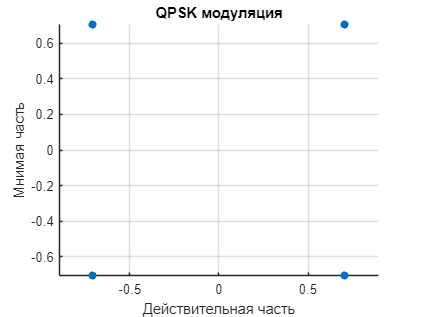

fprintf("\n");
% Отображение QPSK символов на комплексной плоскости
scatter(real(qpsk_sequence), imag(qpsk_sequence), 'filled');
xlabel('Действительная часть');
ylabel('Мнимая часть');
title('QPSK модуляция');
grid on;
axis equal;


DRS = 3;
pref = 1/4;
[ofdm, Nz, prefix, N_qpsk, OP_ind,INF_ind,OP_sig] = ofdm_modulation(qpsk_sequence, DRS, pref);

disp("OFDM");

OFDM


disp(ofdm);

   0.0167 - 0.0683i  -0.0281 + 0.0321i   0.0375 + 0.0646i  -0.0116 - 0.0102i   0.0333 - 0.0322i  -0.0520 - 0.0414i   0.0206 + 0.0104i   0.0114 + 0.0867i  -0.0478 - 0.0496i   0.0339 - 0.0037i   0.0460 - 0.0031i  -0.0266 - 0.0528i  -0.0490 + 0.0591i   0.0108 + 0.0601i   0.0012 - 0.0361i   0.0731 - 0.1058i  -0.0547 + 0.0333i   0.0158 + 0.0994i  -0.0360 + 0.0078i  -0.0493 - 0.1152i   0.1493 + 0.0255i  -0.0710 + 0.0181i  -0.0164 + 0.0435i  -0.0042 + 0.0129i  -0.0225 - 0.1508i   0.1154 + 0.1299i  -0.1404 + 0.0264i   0.0618 - 0.0868i   0.0217 + 0.0517i  -0.0025 - 0.0803i  -0.0456 + 0.1026i   0.0088 - 0.0410i   0.0010 + 0.0372i   0.0642 - 0.0567i  -0.0364 - 0.0337i  -0.0450 + 0.0723i   0.0077 + 0.0062i   0.0428 - 0.0163i   0.0024 - 0.0030i  -0.0170 - 0.0256i  -0.0080 - 0.0184i  -0.0319 + 0.0670i   0.0619 + 0.0065i  -0.0256 - 0.0727i   0.0164 + 0.0527i  -0.0147 - 0.0043i  -0.0267 - 0.0328i   0.0071 - 0.0032i   0.0491 + 0.0402i  -0.0209 + 0.0301i   0.0010 - 0.0472i  -0.0490 - 0.0252i   0.0552 - 

fprintf('Mодуляция ofdm: ');

Mодуляция ofdm: 

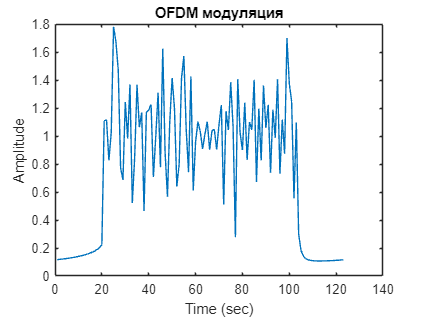

plot(abs(fft(ofdm)));
xlabel("Time (sec)");
ylabel("Amplitude");
title("OFDM модуляция");

%-----------------------------------
Nb = 8;
L = length(ofdm);
B = 11*10^6;
F0 = 1.7* 10^9;
N0 = -100;
Srx = multibeam(Nb,L,B,F0,N0, ofdm);


массив длин:    142   158   215   217   279   372   472   492



%Srx = Channel_Model(ofdm);
fprintf("Srx: ");

Srx: 

disp(Srx);

   1.0e-04 *

   0.0493 - 0.0675i   0.0535 - 0.0289i   0.0206 + 0.0925i   0.1317 - 0.0414i   0.0184 + 0.0010i  -0.0430 - 0.0199i  -0.2357 - 0.0236i   0.2776 + 0.0856i  -0.1648 - 0.0568i   0.0343 - 0.0384i   0.1347 + 0.1099i  -0.0302 - 0.1181i  -0.0952 + 0.0178i  -0.0670 + 0.0575i  -0.0083 - 0.0205i   0.1923 - 0.0133i  -0.0859 - 0.0406i   0.0292 + 0.0878i   0.1186 - 0.0211i  -0.1754 - 0.0730i   0.0260 + 0.0311i  -0.0397 + 0.0749i  -0.1204 - 0.0563i   0.0432 + 0.0320i  -0.1667 - 0.1571i   0.0609 + 0.1360i  -0.0970 + 0.1768i  -0.0640 - 0.3219i   0.1949 + 0.1386i  -0.2435 - 0.0291i   0.1138 + 0.0296i  -0.2843 + 0.1040i   0.1621 - 0.2300i   0.3236 + 0.1981i   0.0491 - 0.1494i  -0.1127 + 0.1250i   0.0988 - 0.0457i  -0.0743 - 0.0705i   0.1760 + 0.1317i   0.0527 - 0.0707i   0.1132 - 0.0211i  -0.0896 + 0.0186i   0.0362 + 0.0194i  -0.0627 - 0.0472i  -0.0820 + 0.0635i   0.0551 + 0.0294i  -0.1830 - 0.1245i  -0.0853 + 0.0418i  -0.0116 + 0.0102i  -0.1705 + 0.0715i   0.0813 - 0.0293i  -0.0229 - 0.067

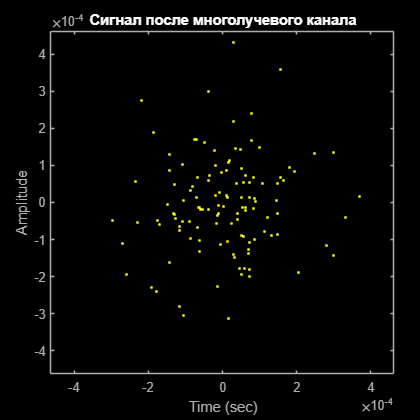

scatterplot(fft(Srx));
xlabel("Time (sec)");
ylabel("Amplitude");
title("Сигнал после многолучевого канала");

%----------------------------------

signal = ofdm_demodulation(Srx, Nz, prefix, OP_ind, INF_ind,OP_sig);



qpsk_desequence = qpsk_demodulation(signal); % демодуляция qpsk
fprintf("Демодуляция qpsk: ");

Демодуляция qpsk: 

for t = 1:length(qpsk_desequence)
fprintf("%d  ",qpsk_desequence(t));
end

0  0  0  0  1  0  0  0  0  0  0  1  1  1  1  0  0  0  1  1  0  1  0  0  0  1  1  0  1  0  0  0  0  0  0  0  0  1  1  0  0  0  1  0  0  1  1  1  0  0  1  1  1  1  1  1  1  1  0  1  0  0  1  0  0  0  1  1  0  0  1  1  1  0  1  0  1  0  1  0  0  0  0  1  1  0  0  1  0  0  1  0  0  0  1  0  

fprintf("\n");

deinterleave_massage = deinterleave(interleave_massage, ran_index);
dis = sprintf("\nБитовая последовательность после деперемежения: \n");
disp(dis);


Битовая последовательность после деперемежения: 



disp(num2str(deinterleave_massage));

1  1  0  1  0  1  1  1  0  1  0  1  0  0  0  1  1  1  0  0  0  0  1  0  0  0  0  1  1  1  1  1  0  1  1  1  1  1  0  0  1  0  1  1  0  0  1  1  1  0  1  0  0  1  1  0  1  0  0  1  1  0  1  0  1  1  1  0  0  0  0  1  0  0  1  0  0  0  0  0  0  1  0  0  1  1  0  1  0  1  0  0  0  1  0  1  1  1



dis = sprintf("\nБитовая последовательность после дешифрования: \n");
disp(dis);


Битовая последовательность после дешифрования: 



conv_decode_massage = conv_decode(deinterleave_massage, bit);
disp(num2str(conv_decode_massage));

1  1  0  1  0  1  1  1  0  1  0  1  1  1  0  0  1  1  0  1  1  1  0  0  0  0  1  1  1  1  0  1  0  1  1  1  1  1  1  0  1  1  0  1  1  0  1  1  1


massage_str = decode(conv_decode_massage, bit);
dis = sprintf("\nДекодированное сообщение: %s", massage_str);
disp(dis);


Декодированное сообщение: kulakov
